## Problem 4

clear;
rng(0);

Consider a continuous random variable $X$ that has an M-shaped probability density function (PDF) $P_X(\cdot )$ as follows: 

$P_X(x) := 0$ for $|x| > 1$, and $P_X(x) := |x|$ for $x \in [-1, 1]$. 

Consider independent continuous random variables $\left\{X_i : i = 1, 2, \cdots , \infty \right\}$ with PDFs identical to that of $X$. 

Define random variables 

$Y_N := \frac{1}{N} \sum_{i=1}^N X_i$ ,

 for $N = 1, 2, \cdots , \infty$, which have associated distributions $P_{Y_N} (\cdot)$. 

- Write code to generate independent draws from $P_X(\cdot )$. Your code can use only the uniform random number generator rand() (no other generator). Submit this code.

 mprob = sign(2*rand( )-1).*sqrt(abs(2*rand( )-1));   % transformation from rand() to the random variable whose PDF is the M graph

- Show plots of (i) the histogram (with 200 bins) and (ii) cumulative distribution function (CDF), both using $M := 10^5$ draws from the PDF $P_X(\cdot )$. 

M = 10^5;     % number of draws

dataset = sign(2*rand(M,1)-1).*sqrt(abs(2*rand(M,1)-1))    % dataset corresponding to the number of draws

dataset =    -0.3045
    0.6837
    0.5101
   -0.8938
   -0.3670
    0.5487
    0.8334
    0.7143
   -0.9732
    0.5402


pdf =   Histogram with properties:

             Data: [100000×1 double]
           Values: [201 1057 964 1046 977 1002 947 907 989 901 853 825 914 906 842 862 836 863 820 778 803 791 771 800 717 753 796 764 716 738 728 730 713 671 626 636 610 602 633 617 567 574 605 573 488 559 534 540 542 468 481 509 461 474 482 447 434 … ]
          NumBins: 200
         BinEdges: [-1.0080 -0.9980 -0.9879 -0.9779 -0.9678 -0.9578 -0.9478 -0.9377 -0.9277 -0.9176 -0.9076 -0.8976 -0.8875 -0.8775 -0.8674 -0.8574 -0.8474 -0.8373 -0.8273 -0.8172 -0.8072 -0.7972 -0.7871 -0.7771 -0.7670 -0.7570 -0.7470 -0.7369 … ]
         BinWidth: 0.0100
        BinLimits: [-1.0080 1.0000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show 

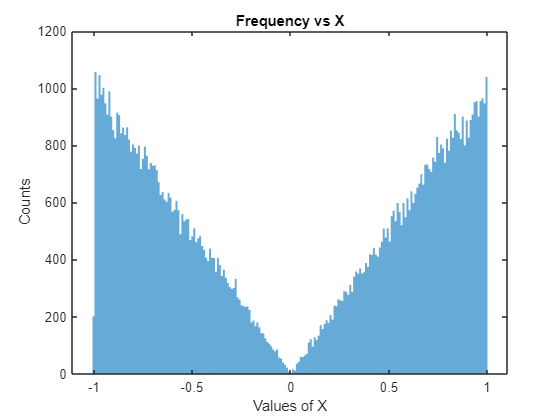

pdf = histogram(dataset,200,'EdgeColor','none'), xlabel("Values of X"), ylabel("Counts"), title("Frequency vs X");   % Plot the histogram - reflects the empirical PDF

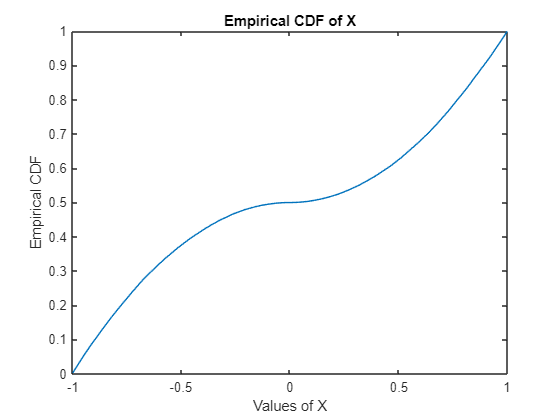

cdf = cumsum(pdf.Values)/sum(pdf.Values);
x = linspace(-1, 1, 200);
plot(x, cdf), xlabel("Values of X"), ylabel("Empirical CDF"), title("Empirical CDF of X");

- Use the code written in the previous sub-question to write code to generate independent draws from $P_{Y_N} (\cdot)$. Submit this code.

% see the last function in this code
% function pyn = avg_M(N)
%     pyn = mean(sign(2*rand(N,1)-1).*sqrt(abs(2*rand(N,1)-1)));
% end

- Show plots (separately) of histograms using $10^4$ draws from each of the PDFs $P_{Y_N} (\cdot)$ for $N = 2, 4, 8, 16, 32, 64$. Show plots, on the same graph, of all the CDFs associated with $Y_N$ for $N = 1, 2, 4, 8, 16, 32, 64$, computed using $10^4$ draws from each $P_{Y_N} (\cdot)$. Plot each CDF curve using a different color. You may use the cdfplot(.) function in Matlab.

N = [2,4,8,16,32,64]    % values of N

N =      2     4     8    16    32    64


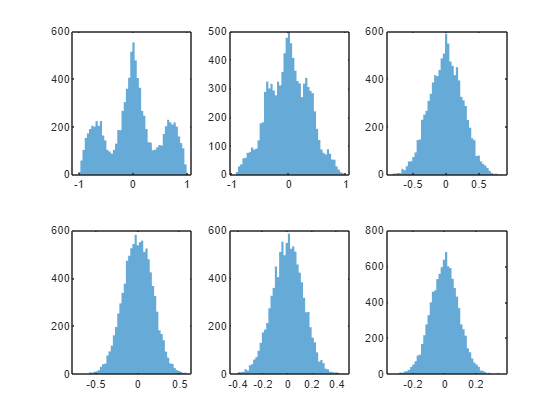

reps=10^4;    % number of draws 
figure;
j = 1;
for n=N
    data = zeros(reps,1);     
    for i=(1:reps)
        data(i)=avg_M(n);     % data for a particular N
    end
    subplot(2, 3, j);    
    histogram(data, 50,"EdgeColor",'none');   % plot the histogram for particular N
    j = j+1;     
    hold off;
end 

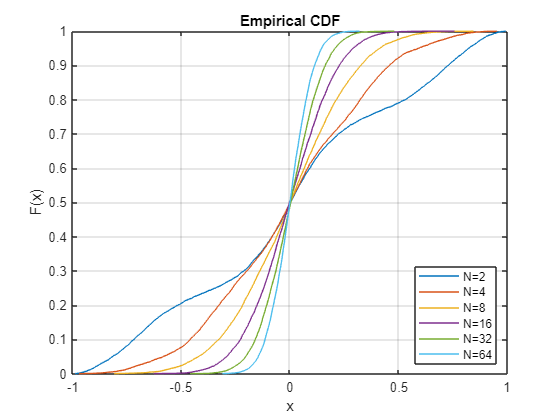

figure; % for the joint cdf plot
for n=N
    data = zeros(reps,1);
    for i=(1:reps)
        data(i)=avg_M(n);    % data for a particular N
    end

    cdfplot(data);
    hold on;
end 
legend('N=2','N=4','N=8','N=16','N=32','N=64','Location','southeast')

%Live scripts require functions to be at the end.
% generates size N array of random variables with the M type probability
% distribution to get Y_N

function pyn = avg_M(N) %Generates (Y_N) as a function of N
    pyn = mean(sign(2*rand(N,1)-1).*sqrt(abs(2*rand(N,1)-1)));
end